gunzip('https://github.com/sp-au-mu-nl/SpeechComm/raw/refs/heads/main/data/chap03.zip','data')

unzip('data/chap03.zip', 'data/chap03/')

プログラム 3.2

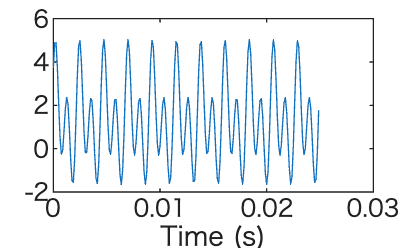

sr = 8000;
t = (0:sr-1)/sr;
a0 = 1.4; a = [0.9; 1.4]; b = [1.2; 1.8];
f = 440;
n = [1; 2];
y = a0 + sum(a.*cos(2*pi*f*n*t)+b.*sin(2*pi*f*n*t),1);

r = 1:200;
plot(t(r), y(r))
xlabel('Time (s)');


soundsc(y,sr)

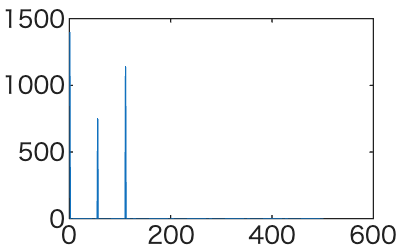

nFFT = 1000;
S = fft(y,nFFT);
plot(abs(S(1:nFFT/2+1)))

S(56)

ans = 4.5000e+02 - 6.0000e+02i

S(111)

ans = 7.0000e+02 - 9.0000e+02i

abs(S(56))

ans = 750.0000

angle(S(56))

ans = -0.9273

プログラム 3.3

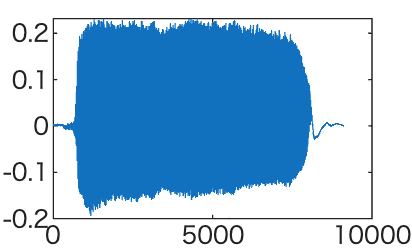

[y, sr] = audioread('data/chap03/a-falsetto.wav');
y = resample(y, 8000, sr);
sr = 8000;
nFFT = 1024;
plot(y)

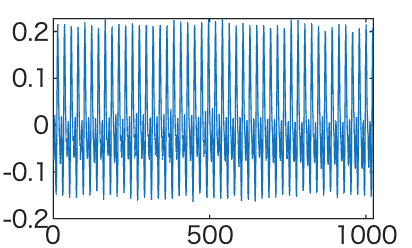

plot(y(2000+(1:nFFT)))

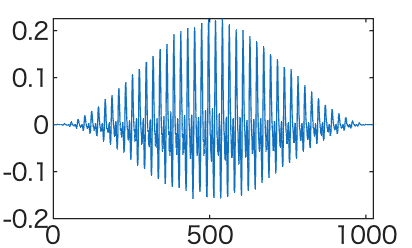

yWindow = y(2000+(1:nFFT)).*hann(nFFT);
plot(yWindow)

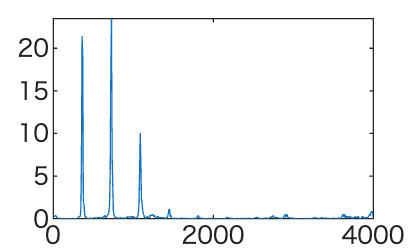

S = fft(yWindow);
frequency = linspace(0,sr/2,nFFT/2+1);
plot(frequency,abs(S(1:nFFT/2+1)))

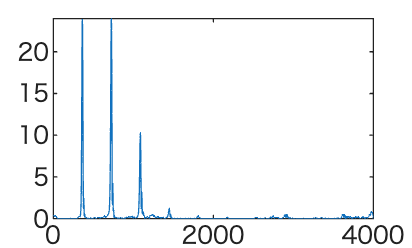

nFFTZP = 8192;
SZeroPadding = fft(yWindow, nFFTZP);
frequencyZeroPadding = linspace(0,sr/2,nFFTZP/2+1);
plot(frequencyZeroPadding, abs(SZeroPadding(1:nFFTZP/2+1)));

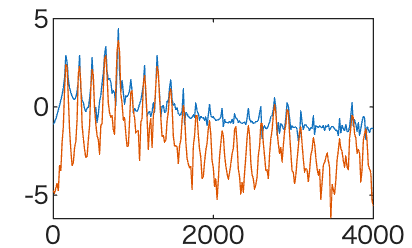

nFFT = 512;
[yA, sr] = audioread('data/chap03/a8k.wav');
yASegment = yA(2000+(1:nFFT));
SARect = fft(yASegment.*rectwin(nFFT));
frequency = linspace(0, sr/2, nFFT/2+1);
plot(frequency, log(abs(SARect(1:nFFT/2+1)))); hold on
SAHann = fft(yASegment.*hann(nFFT));
plot(frequency, log(abs(SAHann(1:nFFT/2+1)))); hold off

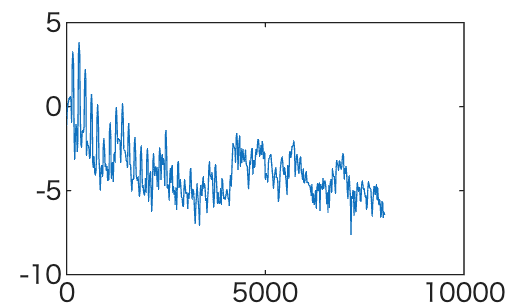

[yAiueo, sr] = audioread('data/chap03/aiueo16k.wav');
nFFT = 1024; nOverlap = 512;
[S, f, t] = stft(yAiueo, sr, "Window", hann(nFFT), ...
    "OverlapLength", nOverlap, "FrequencyRange", "onesided"); % scipy のものとは両端の処理が異なる
plot(f, log(abs(S(:,20))))

プログラム 3.4

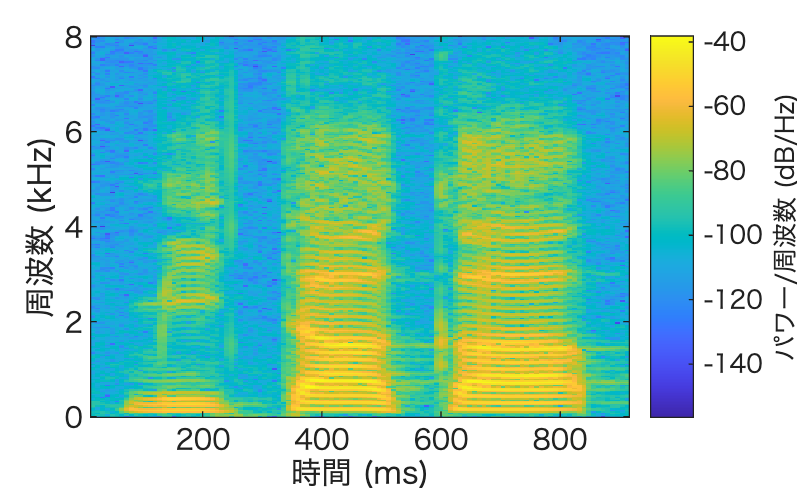

[yMitaka, sr] = audioread('data/chap03/mitaka48k.wav');
yMitaka = resample(yMitaka, 16000, sr);
sr = 16000;
nFFT = 512; nShift = 128;
spectrogram(yMitaka, hann(nFFT), nFFT - nShift, nFFT, sr, 'yaxis')

プログラム 3.5

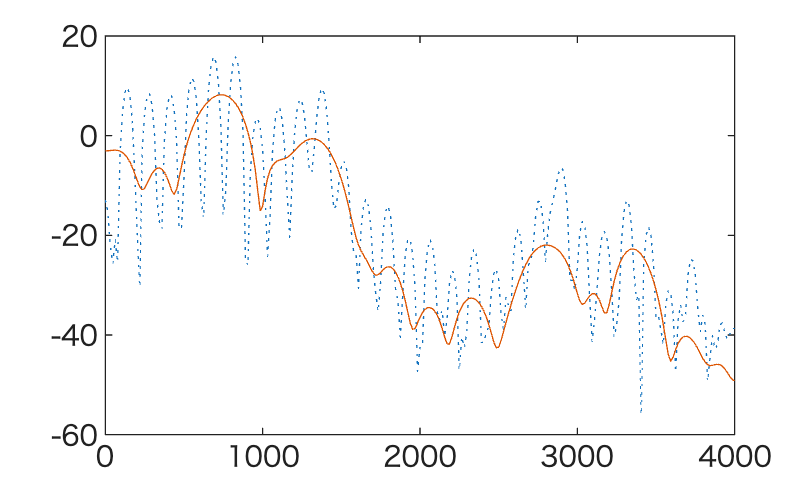

[ySa, sr] = audioread('data/chap03/sa48k.wav');
ySa = resample(ySa, 8000, sr);
sr = 8000; nNarrow = 256; nWide = 64;
SNarrow = fft(ySa(3200+(1:nNarrow)).*hann(nNarrow), nFFT);
frequency = linspace(0, sr/2, nFFT/2+1);
plot(frequency, 20*log10(abs(SNarrow(1:nFFT/2+1))), ':'); hold on
SWide = fft(ySa(3200+(1:nWide)).*hann(nWide), nFFT);
plot(frequency, 20*log10(abs(SWide(1:nFFT/2+1)))); hold off

プログラム 3.6

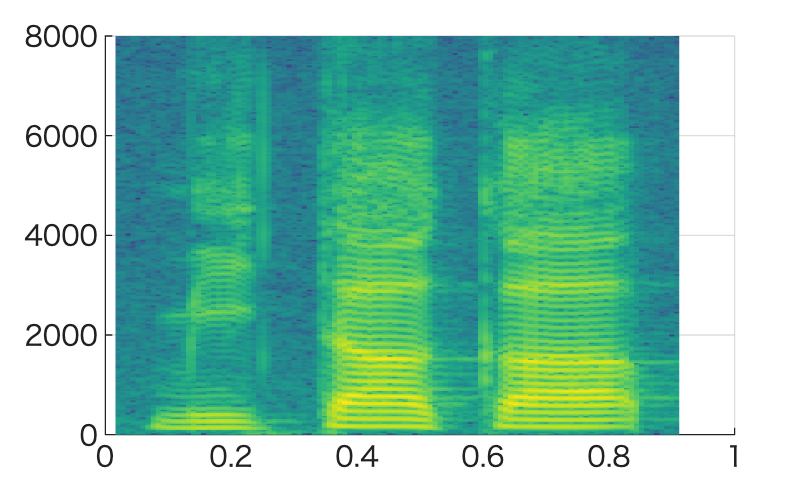

[yMitaka, sr] = audioread('data/chap03/mitaka48k.wav');
yMitaka = resample(yMitaka, 16000, sr);
sr = 16000;
nFFT = 512; nShift = 128;
[SMitaka, f, t] = stft(yMitaka, sr, "Window", hann(nFFT), ...
    "OverlapLength", nFFT - nShift, "FrequencyRange", "onesided");
surf(t, f, 20*log10(abs(SMitaka)), 'EdgeColor','none'); view(0, 90)
colormap(viridis)